##  0. Housekeeping

clear;
addpath('Figures');
addpath('Figures/Figs');
addpath('Functions');
addpath('Mats');
addpath('Mats - Consumption');
addpath('Mats - Distributions');
addpath('Mats - Job Value and Wage');
addpath('Mats - Savings')
addpath('Mats - Value Function');
addpath('Mats - Welfare');
addpath('Results');

## 1. Structural Parameter Settings

### 1.1. Structural Parameters

global I J daaF daaB dz lame amin amax gam aagrid zgrid;
alf  = 0.3;     % Production Parameter          fr. Bardoczy
bet  = 0.72;    % Worker's bargaining power     fr. Bardoczy    
gam  = 1;       % Utility function              fr. Ben Moll Aiyagari Diffusion
del  = 0.021;   % Depreciation Rate             fr. Ben Moll Aiyagari Diffusion
eta  = 0.72;    % LM Tightness Elasticity       fr. Bardoczy
phi  = 0.395;   % Flow Cost of Vacancy          fr. Bardoczy (It's \xi in Bardoczy)
rho  = 0.01;    % Discount rate                 fr. Ben Moll Aiyagari Diffusion
chi  = 1.7935;  % Matching Efficiency           fr. Bardoczy                
lame = 0.1038;  % Separation Intensity          fr. Bardoczy and several other liter0ature
hp   = 0.0001;  % Home Production

### 1.2. Asset Grid

amin = 0; 
amax = 2500;
I = 1500;
J = 15;
x = linspace(0,1,I)';
coeff = 1.3; power = 2.8;
xx  = x + coeff*x.^power;
xmax = max(xx); 
xmin = min(xx);
agrid = (amax-amin)/(xmax - xmin)*xx + amin;
aagrid = agrid*ones(1,J);

daF = ones(I,1);
daB = ones(I,1);

daF(1:I-1) = agrid(2:I)-agrid(1:I-1);
daB(2:I  ) = agrid(2:I)-agrid(1:I-1);

daF(I) = daF(I-1); 
daB(1) = daB(2);

daaF = repmat(daF,1,J);
daaB = repmat(daB,1,J);

### 1.3. Productivity Grid

ze =  1; 
zu = 0.65;
zmin = zu; 
zmax = ze;

zgrid = linspace(zmin, zmax, J)';
zzgrid = ones(I,1) * zgrid';
zgridREP= repelem(zgrid,I);
dz = (zmax - zmin)/(J-1);

the  = .25;
theu = .50;
mue = the*(ze - zgrid);
muu = the*(zu - zgrid);

## 2. The Transition Matrix for the Diffusion Process  

Ce = MatrixC(mue);
Cu = MatrixC(muu);
C = blkdiag(sparse(Ce), sparse(Cu));

## 3. Solution Parameter Settings

tolHJB = 1e-10;  % tolerance level for HJB equations 12?
tolENT = 1e-5;  % tolerance level for free entry condition
tolMKT = 1e-5;  % tolerance level for asset market clearing
n = 300; % maximum number of iterations when solving HJB equation
N = 1000;  % maximum number of iterations in outer loop
Delta = 500;  % step size in HJB equation
dTheta = 1e-1;  % step size in updating theta
relax = .999;
kgap = 500;

# **Models with Payroll Taxation**

VNames = {'tau','h','maxrr','minrr','arr','ur','k','r','Theta','lamu','zemean','zumean','aa','Va','awg','ac','Vc','ace','Vce','acu','Vcu','Jf'};
VTypes = {'double','double','double','double','double','double','double','double','double','double','double','double','double','double','double','double','double','double','double','double','double','double'};

VONames = {'tau','AO','MO','MMO','EO','UO','MEO','MUO','Benefited','OL'};
VOTypes = {'double','double','double','double','double','double','double','double','double','double'};
Results = table('Size',[0,length(VNames)], 'VariableTypes',VTypes,'VariableNames',VNames);
Omegas = table('Size', [0,length(VONames)],'VariableTypes',VOTypes,'VariableNames',VONames);

Tau = [0];

tic;
for Taxation = 1:length(Tau) % First loop
    tau = Tau(Taxation);
    % Reset
    Delta = 500;
    relax = .999;
    kgap = 500;

##     1. Initial Guess

###          1.1. Updating Parameters

#### **            1.1.1. Labor Market**

    Theta = 1; 
    lamu = chi * (Theta ^ (1 - eta));
    q = chi * (Theta^(-eta));
    u = lame / (lame + lamu);
    v = Theta * u;

#### **            1.1.2. Capital Market and Prices**

    z = KFE4z(mue,muu,lamu,lame);
    k = (((rho+del)/(z*alf))^(1/(alf-1)))*1.01;
    r = z*alf*k^(alf-1);
    wj = bet * ((k^alf)* zgrid' - r * k);
    wg = repmat(wj,I,1);
    wgVEC = wg(:);

###         1.2. Value functions

    We  = zeros(I,  J);
    Wu  = zeros(I,  J);

    WeF = zeros(I, J);
    WeB = zeros(I, J);
    WuF = zeros(I, J);
    WuB = zeros(I, J);

    Jf  = (repelem(zgrid,I) *k^alf - r*k - wgVEC) / (lame + r - del);

###         1.3. Unemployment benefits

    upop = (lame)/(lamu+lame);
    [epop,upop] = (zDistribution(mue,muu,lamu,lame));
    govrev = (tau*wj)*epop;
    %mwg = (wj*epop)/sum(epop);
    %wjj = min(wj,mwg*ones(1,J));
    h = govrev/(sum(upop));
    h = h*ones(I,J);

##     2. Solution

####             (The Outer Loop)

    for outerloop = 1:N

###         2.1. Solving Consumer's HJB

        for innerloop = 1:n

#### **            2.1.1. The Employed**

            WeB(2:I,   :) = (We(2:I,   :)-We(1:I-1, :)) ./ (aagrid(2:I,:) - aagrid(1:I-1,:));
            WeF(1:I-1, :) = (We(2:I,   :)-We(1:I-1, :)) ./ (aagrid(2:I,:) - aagrid(1:I-1,:));
            WeB(1,:) = (wg(1,:)*(1-tau) + (r-del)*amin).^(-gam);
            WeF(I,:) = (wg(I,:)*(1-tau) + (r-del)*amax).^(-gam);
            ceB = max(WeB, 1e-6).^(-1/gam);
            ceF = max(WeF, 1e-6).^(-1/gam);
            ce0 = wg*(1-tau) + (r-del)*aagrid;
            Complex_Check(ceB);
            Complex_Check(ceF);
            seB = wg*(1-tau) + (r-del)*aagrid - ceB;
            seF = wg*(1-tau) + (r-del)*aagrid - ceF;
            HeF = log(ceF) + WeF.*seF;
            HeB = log(ceB) + WeB.*seB;
            IeEither = (1-(seF>0)) .* (1-(seB<0)); % using central 
            IeUnique = (seB<0).*(1-(seF>0)) + (1-(seB<0)).*(seF>0); % Ideal
            IeBoth   = (seB<0).*(seF>0); % Problematic
            IeB = IeUnique.*(seB<0) + IeBoth.*(HeB>=HeF);
            IeF = IeUnique.*(seF>0) + IeBoth.*(HeF>=HeB);
            Ie0 = IeEither;
            ce  = IeF.*ceF + IeB.*ceB + Ie0.*ce0;
            xie = wg*(1-tau) + (r-del).*aagrid - ce;
            Ae  = MatrixA(seB,seF,IeB,IeF);

####             2.1.2. The Unemployed

            WuB(2:I,   :) = (Wu(2:I,  :)-Wu(1:I-1, :)) ./ (aagrid(2:I,:) - aagrid(1:I-1,:));
            WuF(1:I-1, :) = (Wu(2:I,  :)-Wu(1:I-1, :)) ./ (aagrid(2:I,:) - aagrid(1:I-1,:));
            WuB(1, :) = (hp + h(1,:) + (r-del)*amin).^(-gam); 
            WuF(I, :) = (hp + h(I,:) + (r-del)*amax).^(-gam); 
            cuB = max(WuB, 1e-6).^(-1/gam);
            cuF = max(WuF, 1e-6).^(-1/gam);
            cu0 = hp + h + (r-del).*aagrid;
            suB = hp + h + (r-del)*aagrid - cuB;
            suF = hp + h + (r-del)*aagrid - cuF;
            HuF = log(cuF) + WuF .* suF;
            HuB = log(cuB) + WuB .* suB;
            IuEither = (1-(suF>0)) .* (1-(suB<0));
            IuUnique = (suB<0).*(1-(suF>0)) + (1-(suB<0)).*(suF>0);
            IuBoth   = (suB<0).*(suF>0);
            IuB = IuUnique.*(suB<0) + IuBoth.*(HuB>=HuF);
            IuF = IuUnique.*(suF>0) + IuBoth.*(HuF>=HuB);
            Iu0 = IuEither;
            cu = IuF.*cuF + IuB.*cuB + Iu0.*cu0;
            xiu = hp + h + (r-del).*aagrid - cu;
            Au = MatrixA(suB,suF,IuB,IuF);
            
            c = [ce(:); cu(:)];
            if gam == 1
                utility = log(c);
            else
                utility = (c.^(1-gam)) / (1-gam);
            end

#### **            2.1.4. Creating the new matrix Lambda**

            Lam = MatrixLam(lamu);
            A = blkdiag(sparse(Ae), sparse(Au)) + C + Lam;

#### **            2.1.5. Solving the Linear Algebra**

            Dn = (1/Delta + rho)*speye(I*J*2) - A;
            Waz = [We(:);Wu(:)];
            dn = utility + Waz / Delta;
            WazNEW = Dn\dn;
            WeNEW = reshape(WazNEW(1:(I*J)), I, J);
            WuNEW = reshape(WazNEW((I*J)+1:end), I, J);
        
            distHJB = max(abs(WazNEW-Waz));
        
            if distHJB < tolHJB
                disp(['Value Function "Consumer HJB" Converged, Iteration = ', num2str(innerloop)]);
                break
            end
            % Update
            We = WeNEW; 
            Wu = WuNEW;
        end % Consumption innerloop ends 

###         2.2. Solving Consumer's Fokker-Planck Equation    

####             2.2.1. Setting up (fixing one value)

        da_tilde = 0.5*(daB+daF);
        da_tilde(1,:) = 0.5*daF(1,:);
        da_tilde(I,:) = 0.5*daB(I,:);
        da_stacked = repmat(da_tilde,2*J,1);
        grid_diag = dz*spdiags(da_stacked,0,I*J*2,I*J*2);
        M = I*J*2;
        fix = 1;
        AT = A';
        null = zeros(M,1);
        null(fix) = 1;
        AT(fix,:) = [zeros(1,fix-1),1,zeros(1, M-fix)];
        gVEC = AT\null;
        gsum = gVEC' * repmat(da_tilde,2*J,1)*dz;
        g = gVEC./ gsum;
        ge = g(1:I*J);
        gu = g(I*J+1:end);

###         2.3. Solving Firm's HJB Equation

        wgVEC = wg(:);
        pi = repelem(zgrid,I)*(k^alf) - r*k - wgVEC;
        En = (1/Delta + lame + r - del)*speye(I*J) - Ae - Ce;

        for i = 1:n
            en = pi + Jf/Delta;
            Jfnew = En\en;
            distfirmHJB = max(abs(Jfnew - Jf));
            if distfirmHJB < tolHJB
                break
            end
            Jf = Jfnew;
        end

### 2.5. Wage Bargaining

        JfIJ = reshape(Jf,I,J);
        dW = ce.^(-gam);

        ue = log(ce);

        dJf = [diff(JfIJ,1,1)./ diff(aagrid,1,1); zeros(1,J)];
        term1 = (zzgrid*(k^alf)  - r*k + dJf.*((r-del)*aagrid - ce)) ./ (1-dJf);
        term2 = (ue + dW.* ((r-del)*aagrid - ce) - rho*Wu) ./ dW;
        wgNEW = bet*term1 - (1-bet)*term2;
        Y = reshape(repelem(zgrid,I)*(k^alf) - r*k,I,J);
        wgNEW = min(wgNEW,Y);
        wgNEW = max((h+hp)/(1-tau),wgNEW);

        if any(wgNEW(:) < 0)
            disp('Non-positive number found in wgNEW.');
        end

        clear dW ue dJf term1 term2 Y;

###         2.5. Market Clearing

####             2.5.1. Free Entry Condition

        VV = -phi + (lamu/Theta) * Jf' * ((gu/u) .* repmat(da_tilde,J,1)*dz); 

####             2.5.2. Reporting the Equilibirum

        revenu = sum(sum(tau*wg.*reshape(ge,I,J).*repmat(da_tilde,1,J)*dz));
        expend = sum(sum(     h.*reshape(gu,I,J).*repmat(da_tilde,1,J)*dz));

####             2.5.3. Asset Market Clearing

**                2.5.3.1. Asset Demand**

        azazgrid = repmat(agrid,J,1);
        aggregatesavings = azazgrid' * ((ge+gu).*repmat(da_tilde,J,1)*dz);
        kas = aggregatesavings/(1-u);
        kgap = k - kas;

        if abs(VV) < tolENT && abs(kgap) < tolMKT
            disp(['Found the equilibrium! Theta = ', num2str(Theta), 'r = ', num2str(r)])
            break
        else
            disp(['OL:',num2str(outerloop),'VV:',num2str(VV),'kgap:',num2str(kgap),"tau:",num2str(tau),"maxrrate:",num2str(max(max(h./wg)))])   
        end 

###         2.7. Updating Parameters

####             2.7.1. Labor Market

        Theta = Theta + dTheta * VV;
        lamu = chi * (Theta ^ (1 - eta));
        q = chi * (Theta^(-eta));
        u = lame / (lame + lamu);
        v = Theta * u;

####             2.7.2. Capital Market and Prices

        k = relax*k +(1-relax)*kas;
        z = KFE4z(mue,muu,lamu,lame);
        r = z*alf*k^(alf-1);
        wg = wgNEW; 
        clear wgNEW;

####             2.7.3. Unemployment Insurance 

        govrev = sum(sum((tau*wg).*reshape(ge,I,J).*repmat(da_tilde,1,J)*dz));
        h = govrev/(sum(sum(reshape(gu,I,J).*repmat(da_tilde,1,J)*dz)));
        h = h*ones(I,J);
        disp(['maxnrr:',num2str(max(max((hp+h)./wg*(1-tau))))]);
    end

    load('median_center.mat'); mc = median_center; clear median_center;
    load('mediane.mat');
    load('medianu.mat');
    load('We_bm.mat')  ;
    load('Wu_bm.mat')  ;
    load('medast.mat') ;
    load('Ge_bm.mat')  ;
    load('Gu_bm.mat')  ;

    Ge = reshape(ge,I,J) .* repmat(da_tilde,1,J) * dz; clear ge;
    Gu = reshape(gu,I,J) .* repmat(da_tilde,1,J) * dz; clear gu;

    %ge = reshape(ge,I,J);
    %gu = reshape(gu,I,J);
    avrwg = sum(sum(wg.*Ge))/(sum(sum(Ge)));
    maxnrr = max(max((h./(wg*(1-tau)))));
    minnrr = min(min((h./(wg*(1-tau)))));
    anrr = mean(mean(h))/(avrwg*(1-tau));
    avrast = sum(sum(aagrid.*(Ge+Gu)));
    avrcon = sum(sum(ce.*Ge + cu.*Gu));
    avrcone = sum(sum(ce.*Ge))/(sum(sum(Ge)));
    avrconu = sum(sum(cu.*Gu))/(sum(sum(Gu)));
    
    VA = sum(sum(((aagrid-avrast).^2).*(Ge+Gu))); 
    VC = sum(sum(((ce-avrcon).^2).*Ge + ((cu-avrcon).^2).*Gu));
    VCe = sum(sum(((ce-avrcone).^2).*(Ge/(sum(sum(Ge))))));
    VCu = sum(sum(((cu-avrconu).^2).*(Gu/(sum(sum(Gu))))));

    EJf = sum(sum(JfIJ .* Gu))/(sum(sum(Gu)));
    ur = lame/(lame+lamu);
    zemean = KFE4z(mue, muu, lamu, lame);
    zumean = sum(sum(zzgrid.*Gu))/(sum(sum(Gu)));
    Results = [Results; {tau,h(100,10),maxnrr,minnrr,anrr,ur,k,r,Theta,lamu,zemean,zumean,avrast,VA,avrwg,avrcon,VC,avrcone,VCe,avrconu,VCu,EJf}];

    Omega_e = exp((We-We_bm)*(rho)) - 1;
    Omega_u = exp((Wu-Wu_bm)*(rho)) - 1;
    
    AO = sum(sum(Omega_e(1:100,:).*Ge_bm(1:100,:)+Omega_u(1:100,:).*Gu_bm(1:100,:)))/(sum(sum(Ge_bm(1:100,:)+Gu_bm(1:100,:))));
    MO = sum(sum(Omega_e.*(Ge_bm.*medast)+Omega_u.*(Gu_bm.*medast))) / (sum(sum(((Ge_bm+Gu_bm).*medast))));
    MMO = (Omega_e(mc,:) * Ge_bm(mc,:)' + Omega_u(mc,:) * Gu_bm(mc,:)') / (sum(Ge_bm(mc,:)+Gu_bm(mc,:)));
    EO = (sum(sum(Omega_e(1:100,:).*Ge_bm(1:100,:))))/ (sum(sum(Ge_bm(1:100,:))));
    UO = (sum(sum(Omega_u(1:100,:).*Gu_bm(1:100,:))))/ (sum(sum(Gu_bm(1:100,:))));
    MEO = Omega_e(mediane,15);
    MUO = Omega_u(medianu,13);

    Be  = Omega_e(1:100,:) > 0;
    Bu  = Omega_u(1:100,:) > 0;
    Benefited = sum(sum(Be.*Ge_bm(1:100,:) + Bu.*Gu_bm(1:100,:)))/(sum(sum(Ge_bm(1:100,:)+Gu_bm(1:100,:))));

    Omegas = [Omegas;{tau,AO,MO,MMO,EO,UO,MEO,MUO,Benefited,outerloop}];

    taupct = num2str(round(100*tau,2));

### Plot 1: Distribution - Employed

    figure('Position', [100, 100, 800, 600]);
    surf(aagrid(1:100,:),zzgrid(1:100,:),Ge(1:100,:),'Edgealpha',.25);
    xlim([agrid(1), agrid(100)]);
    xlabel('Asset level (a)','FontSize',16);
    ylabel('Productivity (z)','FontSize',16);
    zlabel('Density','FontSize',16);
    zlim([0 0.05]);
    zticks(0:0.005:0.035);
    colormap(cool);
    filenamefig = sprintf('Figures/Figs/Surfplot - Distribution - Employed - %s.fig', taupct);
    filenamepng = sprintf('Figures/Surfplot - Distribution - Employed - %s.png', taupct);
    savefig(filenamefig);
    exportgraphics(gca, filenamepng, 'Resolution', 300);

###         Plot 2: Distribution - Unemployed

    figure('Position', [100, 100, 800, 600]);
    surf(aagrid(1:100,:),zzgrid(1:100,:),Gu(1:100,:),'Edgealpha',.25);
    xlim([agrid(1), agrid(100)]);
    xlabel('Asset level (a)','FontSize',16);
    ylabel('Productivity (z)','FontSize',16);
    zlabel('Density','FontSize',16);
    colormap(cool);
    zlim([0 0.00075]);
    zticks(0:0.00025:0.00075);
    filenamefig = sprintf('Figures/Figs/Surfplot - Distribution - Unemployed - %s.fig', taupct);
    filenamepng = sprintf('Figures/Surfplot - Distribution - Unemployed - %s.png', taupct);
    savefig(filenamefig);
    exportgraphics(gca, filenamepng, 'Resolution', 300);

###         Plot 3: Productivity Distribution

    figure('Position', [100, 100, 800, 600]);
    plot(zgrid,sum(Ge,1)/(sum(sum(Ge))),'b-', 'LineWidth', 1);
    hold on;
    plot(zgrid,sum(Gu,1)/(sum(sum(Gu))),'r-', 'LineWidth', 1);
    xlabel("Productivity",'FontSize',16);
    ylabel("Density (in each group)",'FontSize',16);
    legend("Employed", "Unemployed");
    filenamefig = sprintf('Figures/Figs/Plot - zDistribution - %s.fig', taupct);
    filenamepng = sprintf('Figures/Plot - zDistribution - %s.png', taupct);
    savefig(filenamefig);
    exportgraphics(gca, filenamepng, 'Resolution', 300);

###         Plot 4: The Savings Difference - Productivity (15)

    figure('Position', [100, 100, 800, 600]);
    plot(agrid(1:100),xie(1:100, 15), 'b-', 'LineWidth', 1.5);
    hold on;
    plot(agrid(1:100),xiu(1:100, 15), 'r-', 'LineWidth', 1.5);
    yline(0, '--k', 'LineWidth', 1);
    xlabel("Asset",'FontSize',16);
    ylabel("Savings",'FontSize',16);
    legend("Employed", "Unemployed");
    xlim([agrid(1), agrid(100)]);
    ylim([-2.0 2.0]);             
    yticks(-2.0:0.25:2.0);         
    filenamefig = sprintf('Figures/Figs/Plot - Difference in Savings - 15 - %s.fig', taupct);
    filenamepng = sprintf('Figures/Plot - Difference in Savings - 15 - %s.png', taupct);
    savefig(filenamefig);
    exportgraphics(gca, filenamepng, 'Resolution', 300);

###         Plot 5: The Savings Difference - Productivity (12)

    figure('Position', [100, 100, 800, 600]);
    plot(agrid(1:100),xie(1:100,12), 'b-', 'LineWidth', 1.5);
    hold on;
    plot(agrid(1:100),xiu(1:100,12), 'r-', 'LineWidth', 1.5);
    yline(0, '--k', 'LineWidth', 1);
    xlabel("Asset",'FontSize',16);
    ylabel("Savings",'FontSize',16);
    legend("Employed", "Unemployed");
    xlim([agrid(1), agrid(100)]);
    ylim([-2.0 2.0]);             
    yticks(-2.0:0.25:2.0);         
    filenamefig = sprintf('Figures/Figs/Plot - Difference in Savings - 12 - %s.fig', taupct);
    filenamepng = sprintf('Figures/Plot - Difference in Savings - 12 - %s.png', taupct);
    savefig(filenamefig);
    exportgraphics(gca, filenamepng, 'Resolution', 300);


###         Plot 6: The Savings Difference - Productivity (9)

    figure('Position', [100, 100, 800, 600]);
    plot(agrid(1:100),xie(1:100,9), 'b-', 'LineWidth', 1.5);
    hold on;
    plot(agrid(1:100),xiu(1:100,9), 'r-', 'LineWidth', 1.5);
    yline(0, '--k', 'LineWidth', 1);
    xlabel("Asset",'FontSize',16);
    ylabel("Savings",'FontSize',16);
    legend("Employed", "Unemployed");
    xlim([agrid(1), agrid(100)]);
    ylim([-2.0 2.0]);             
    yticks(-2.0:0.25:2.0);         
    filenamefig = sprintf('Figures/Figs/Plot - Difference in Savings - 09 - %s.fig', taupct);
    filenamepng = sprintf('Figures/Plot - Difference in Savings - 09 - %s.png', taupct);
    savefig(filenamefig);
    exportgraphics(gca, filenamepng, 'Resolution', 300);

###         Plot 7: The Savings Difference - Productivity (6)

    figure('Position', [100, 100, 800, 600]);
    plot(agrid(1:100),xie(1:100,6), 'b-', 'LineWidth', 1.5);
    hold on;
    plot(agrid(1:100),xiu(1:100,6), 'r-', 'LineWidth', 1.5);
    yline(0, '--k', 'LineWidth', 1);
    xlabel("Asset",'FontSize',16);
    ylabel("Savings",'FontSize',16);
    legend("Employed", "Unemployed");
    xlim([agrid(1), agrid(100)]);
    ylim([-2.0 2.0]);             
    yticks(-2.0:0.25:2.0);         
    filenamefig = sprintf('Figures/Figs/Plot - Difference in Savings - 06 - %s.fig', taupct);
    filenamepng = sprintf('Figures/Plot - Difference in Savings - 06 - %s.png', taupct);
    savefig(filenamefig);
    exportgraphics(gca, filenamepng, 'Resolution', 300);

###         Plot 8: The Savings Difference - Productivity (3)

    figure('Position', [100, 100, 800, 600]);
    plot(agrid(1:100),xie(1:100,3), 'b-', 'LineWidth', 1.5);
    hold on;
    plot(agrid(1:100),xiu(1:100,3), 'r-', 'LineWidth', 1.5);
    yline(0, '--k', 'LineWidth', 1);
    xlabel("Asset",'FontSize',16);
    ylabel("Savings",'FontSize',16);
    legend("Employed", "Unemployed");
    xlim([agrid(1), agrid(100)]);
    ylim([-2.0 2.0]);             
    yticks(-2.0:0.25:2.0);         
    filenamefig = sprintf('Figures/Figs/Plot - Difference in Savings - 03 - %s.fig', taupct);
    filenamepng = sprintf('Figures/Plot - Difference in Savings - 03 - %s.png', taupct);
    savefig(filenamefig);
    exportgraphics(gca, filenamepng, 'Resolution', 300);

###         Plot 9: Job Values

    figure('Position', [100, 100, 800, 600]);
    surf(aagrid(1:100,:),zzgrid(1:100,:),JfIJ(1:100,:),'Edgealpha',.5,'FaceAlpha',.25);
    zlim([0 1.4]);   % Set z-axis limits
    zticks(0:0.2:1.4); % Set z-axis intervals
    xlabel('Asset level (a)','FontSize',16);
    ylabel('Productivity (z)','FontSize',16);
    zlabel('Job Value','FontSize',16);
    zlim([0 1.4]);
    zticks(0:0.35:1.4);    
    colormap(winter);
    filenamefig = sprintf('Figures/Figs/Plot - Job Value - %s.fig', taupct);
    filenamepng = sprintf('Figures/Plot - Job Value - %s.png', taupct);
    savefig(filenamefig);
    exportgraphics(gca, filenamepng, 'Resolution', 300);

###         Plot 13 Asset Distribution

    adistribution = sum(Ge+Gu,2);
    cumadistribution = cumsum(adistribution);
    fq = find(cumadistribution >= 0.25, 1, 'first');
    median = find(cumadistribution >= 0.5, 1, 'first');
    tq = find(cumadistribution >= 0.75, 1, 'first');
    
    figure('Position', [100, 100, 800, 600]);
    plot(agrid(1:100),adistribution(1:100), 'b-', 'LineWidth', 1.25);
    hold on;
    xline(agrid(median), '--k', 'LineWidth', 1.5);
    xline(agrid(fq), '--', 'Color','#4D4D4D', 'LineWidth', 1.5);
    xline(agrid(tq), '--', 'Color','#4D4D4D', 'LineWidth', 1.5);
    yline(0, '--k', 'LineWidth', 1);
    xlabel("Asset",'FontSize',16);
    ylabel("Density",'FontSize',16);
    xlim([agrid(1), agrid(100)]);
    ylim([0 0.035]);
    yticks(0:0.005:0.035);
    text(agrid(median), 0.0335, sprintf('%.2f',agrid(median)),'HorizontalAlignment','center','VerticalAlignment','top','FontSize',12,'Color','k','BackgroundColor', 'w');
    text(agrid(fq), 0.0335, sprintf('%.2f',agrid(fq)),'HorizontalAlignment','center','VerticalAlignment','top','FontSize',12,'Color','#4D4D4D','BackgroundColor', 'w');
    text(agrid(tq), 0.0335, sprintf('%.2f',agrid(tq)),'HorizontalAlignment','center','VerticalAlignment','top','FontSize',12,'Color','#4D4D4D','BackgroundColor', 'w');
    filenamefig = sprintf('Figures/Figs/Plot - Asset Distribution - %s.fig', taupct);
    filenamepng = sprintf('Figures/Plot - Asset Distribution - %s.png', taupct);
    savefig(filenamefig);
    exportgraphics(gca, filenamepng, 'Resolution', 300);

###         Plot 14 Consumption Difference

    figure('Position', [100, 100, 800, 600]);
    plot(agrid(1:100),100*((cu(1:100,15)-ce(1:100,15))./ce(1:100,15)), 'b-', 'LineWidth', 1);
    hold on;
    plot(agrid(1:100),100*((cu(1:100,3)-ce(1:100, 3))./ce(1:100, 3)), 'r-', 'LineWidth', 1);
    yline(0, '--k', 'LineWidth', 1);
    xlabel("Asset",'FontSize',16);
    ylabel("Percent (%)",'FontSize',16);
    legend("z = 1.0", "z = .73");
    xlim([agrid(1), agrid(100)]);
    ylim([-100, 25]);
    yticks(-100:25:25);
    filenamefig = sprintf('Figures/Figs/Plot - Difference in Consumption - %s.fig', taupct);
    filenamepng = sprintf('Figures/Plot - Difference in Consumption - %s.png', taupct);
    savefig(filenamefig);
    exportgraphics(gca, filenamepng, 'Resolution', 300);

### Plot 14a Consumption Difference - 3D

    figure('Position', [100, 100, 800, 600]);
    surf(aagrid(1:100,:),zzgrid(1:100,:),100*((cu(1:100,:)-ce(1:100,:))./ce(1:100,:)));
    xlabel("Asset",'FontSize',16);
    ylabel("Productivity",'FontSize',16);
    zlabel("Percent (%)");
    xlim([agrid(1), agrid(100)]);
    zlim([-100, 25]);
    zticks(-100:25:25);
    colormap("cool");
    filenamefig = sprintf('Figures/Figs/Plot - Difference in Consumption 3D - %s.fig', taupct);
    filenamepng = sprintf('Figures/Plot - Difference in Consumption 3D - %s.png', taupct);
    savefig(filenamefig);
    exportgraphics(gca, filenamepng, 'Resolution', 300);

Value Function "Consumer HJB" Converged, Iteration = 25


    "OL:"    "1"    "VV:"    "7.6044"    "kgap:"    "11.5759"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00011105


Value Function "Consumer HJB" Converged, Iteration = 16


    "OL:"    "2"    "VV:"    "1.3272"    "kgap:"    "8.0116"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00010767


Value Function "Consumer HJB" Converged, Iteration = 15


    "OL:"    "3"    "VV:"    "0.30681"    "kgap:"    "6.3417"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00010717


Value Function "Consumer HJB" Converged, Iteration = 14


    "OL:"    "4"    "VV:"    "0.056313"    "kgap:"    "5.4336"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00010718


Value Function "Consumer HJB" Converged, Iteration = 14


    "OL:"    "5"    "VV:"    "-0.0059071"    "kgap:"    "4.9371"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00010719


Value Function "Consumer HJB" Converged, Iteration = 13


    "OL:"    "6"    "VV:"    "-0.021054"    "kgap:"    "4.5162"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00010862


Value Function "Consumer HJB" Converged, Iteration = 12


    "OL:"    "7"    "VV:"    "-0.024468"    "kgap:"    "4.1422"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.0001106


Value Function "Consumer HJB" Converged, Iteration = 12


    "OL:"    "8"    "VV:"    "-0.024953"    "kgap:"    "3.7949"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00011278


Value Function "Consumer HJB" Converged, Iteration = 12


    "OL:"    "9"    "VV:"    "-0.024712"    "kgap:"    "3.4681"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00011503


Value Function "Consumer HJB" Converged, Iteration = 12


    "OL:"    "10"    "VV:"    "-0.024295"    "kgap:"    "3.1603"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00011721


Value Function "Consumer HJB" Converged, Iteration = 12


    "OL:"    "11"    "VV:"    "-0.02384"    "kgap:"    "2.8707"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00011928


Value Function "Consumer HJB" Converged, Iteration = 12


    "OL:"    "12"    "VV:"    "-0.023381"    "kgap:"    "2.5994"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00012118


Value Function "Consumer HJB" Converged, Iteration = 12


    "OL:"    "13"    "VV:"    "-0.022925"    "kgap:"    "2.3462"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.0001229


Value Function "Consumer HJB" Converged, Iteration = 12


    "OL:"    "14"    "VV:"    "-0.022476"    "kgap:"    "2.1113"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00012445


Value Function "Consumer HJB" Converged, Iteration = 12


    "OL:"    "15"    "VV:"    "-0.022035"    "kgap:"    "1.8944"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00012584


Value Function "Consumer HJB" Converged, Iteration = 12


    "OL:"    "16"    "VV:"    "-0.0216"    "kgap:"    "1.6951"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00012709


Value Function "Consumer HJB" Converged, Iteration = 12


    "OL:"    "17"    "VV:"    "-0.021174"    "kgap:"    "1.5129"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.0001282


Value Function "Consumer HJB" Converged, Iteration = 12


    "OL:"    "18"    "VV:"    "-0.020754"    "kgap:"    "1.3473"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.0001292


Value Function "Consumer HJB" Converged, Iteration = 12


    "OL:"    "19"    "VV:"    "-0.020343"    "kgap:"    "1.1975"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.0001301


Value Function "Consumer HJB" Converged, Iteration = 12


    "OL:"    "20"    "VV:"    "-0.019939"    "kgap:"    "1.0626"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013091


Value Function "Consumer HJB" Converged, Iteration = 11


    "OL:"    "21"    "VV:"    "-0.019544"    "kgap:"    "0.94163"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013165


Value Function "Consumer HJB" Converged, Iteration = 11


    "OL:"    "22"    "VV:"    "-0.019155"    "kgap:"    "0.83361"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013232


Value Function "Consumer HJB" Converged, Iteration = 11


    "OL:"    "23"    "VV:"    "-0.018775"    "kgap:"    "0.73751"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013293


Value Function "Consumer HJB" Converged, Iteration = 11


    "OL:"    "24"    "VV:"    "-0.018402"    "kgap:"    "0.65227"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013348


Value Function "Consumer HJB" Converged, Iteration = 11


    "OL:"    "25"    "VV:"    "-0.018037"    "kgap:"    "0.57691"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013399


Value Function "Consumer HJB" Converged, Iteration = 11


    "OL:"    "26"    "VV:"    "-0.017679"    "kgap:"    "0.51044"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013445


Value Function "Consumer HJB" Converged, Iteration = 11


    "OL:"    "27"    "VV:"    "-0.017328"    "kgap:"    "0.45196"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013487


Value Function "Consumer HJB" Converged, Iteration = 11


    "OL:"    "28"    "VV:"    "-0.016984"    "kgap:"    "0.4006"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013526


Value Function "Consumer HJB" Converged, Iteration = 11


    "OL:"    "29"    "VV:"    "-0.016646"    "kgap:"    "0.35557"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.0001356


Value Function "Consumer HJB" Converged, Iteration = 11


    "OL:"    "30"    "VV:"    "-0.016316"    "kgap:"    "0.31615"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013592


Value Function "Consumer HJB" Converged, Iteration = 11


    "OL:"    "31"    "VV:"    "-0.015992"    "kgap:"    "0.28167"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013621


Value Function "Consumer HJB" Converged, Iteration = 11


    "OL:"    "32"    "VV:"    "-0.015674"    "kgap:"    "0.25154"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013647


Value Function "Consumer HJB" Converged, Iteration = 11


    "OL:"    "33"    "VV:"    "-0.015363"    "kgap:"    "0.22523"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013671


Value Function "Consumer HJB" Converged, Iteration = 11


    "OL:"    "34"    "VV:"    "-0.015058"    "kgap:"    "0.20227"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013693


Value Function "Consumer HJB" Converged, Iteration = 11


    "OL:"    "35"    "VV:"    "-0.014758"    "kgap:"    "0.18223"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013713


Value Function "Consumer HJB" Converged, Iteration = 11


    "OL:"    "36"    "VV:"    "-0.014465"    "kgap:"    "0.16473"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013731


Value Function "Consumer HJB" Converged, Iteration = 11


    "OL:"    "37"    "VV:"    "-0.014177"    "kgap:"    "0.14946"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013748


Value Function "Consumer HJB" Converged, Iteration = 11


    "OL:"    "38"    "VV:"    "-0.013894"    "kgap:"    "0.13612"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013763


Value Function "Consumer HJB" Converged, Iteration = 11


    "OL:"    "39"    "VV:"    "-0.013617"    "kgap:"    "0.12446"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013777


Value Function "Consumer HJB" Converged, Iteration = 11


    "OL:"    "40"    "VV:"    "-0.013346"    "kgap:"    "0.11426"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013789


Value Function "Consumer HJB" Converged, Iteration = 11


    "OL:"    "41"    "VV:"    "-0.013079"    "kgap:"    "0.10533"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013801


Value Function "Consumer HJB" Converged, Iteration = 11


    "OL:"    "42"    "VV:"    "-0.012818"    "kgap:"    "0.097493"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013811


Value Function "Consumer HJB" Converged, Iteration = 11


    "OL:"    "43"    "VV:"    "-0.012561"    "kgap:"    "0.090612"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013821


Value Function "Consumer HJB" Converged, Iteration = 11


    "OL:"    "44"    "VV:"    "-0.01231"    "kgap:"    "0.084558"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.0001383


Value Function "Consumer HJB" Converged, Iteration = 11


    "OL:"    "45"    "VV:"    "-0.012063"    "kgap:"    "0.079217"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013838


Value Function "Consumer HJB" Converged, Iteration = 11


    "OL:"    "46"    "VV:"    "-0.011821"    "kgap:"    "0.074497"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013845


Value Function "Consumer HJB" Converged, Iteration = 11


    "OL:"    "47"    "VV:"    "-0.011584"    "kgap:"    "0.070315"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013852


Value Function "Consumer HJB" Converged, Iteration = 11


    "OL:"    "48"    "VV:"    "-0.011351"    "kgap:"    "0.066597"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013858


Value Function "Consumer HJB" Converged, Iteration = 11


    "OL:"    "49"    "VV:"    "-0.011123"    "kgap:"    "0.06328"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013863


Value Function "Consumer HJB" Converged, Iteration = 11


    "OL:"    "50"    "VV:"    "-0.010899"    "kgap:"    "0.060315"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013869


Value Function "Consumer HJB" Converged, Iteration = 11


    "OL:"    "51"    "VV:"    "-0.010679"    "kgap:"    "0.057653"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013873


Value Function "Consumer HJB" Converged, Iteration = 11


    "OL:"    "52"    "VV:"    "-0.010463"    "kgap:"    "0.055256"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013877


Value Function "Consumer HJB" Converged, Iteration = 11


    "OL:"    "53"    "VV:"    "-0.010252"    "kgap:"    "0.053085"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013881


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "54"    "VV:"    "-0.010045"    "kgap:"    "0.051113"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013885


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "55"    "VV:"    "-0.0098414"    "kgap:"    "0.049315"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013888


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "56"    "VV:"    "-0.009642"    "kgap:"    "0.047668"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013891


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "57"    "VV:"    "-0.0094465"    "kgap:"    "0.046152"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013894


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "58"    "VV:"    "-0.0092548"    "kgap:"    "0.04475"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013896


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "59"    "VV:"    "-0.0090667"    "kgap:"    "0.043448"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013899


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "60"    "VV:"    "-0.0088824"    "kgap:"    "0.042233"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013901


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "61"    "VV:"    "-0.0087016"    "kgap:"    "0.041096"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013903


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "62"    "VV:"    "-0.0085243"    "kgap:"    "0.040027"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013905


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "63"    "VV:"    "-0.0083505"    "kgap:"    "0.039017"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013907


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "64"    "VV:"    "-0.0081801"    "kgap:"    "0.038061"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013908


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "65"    "VV:"    "-0.008013"    "kgap:"    "0.037151"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.0001391


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "66"    "VV:"    "-0.0078492"    "kgap:"    "0.036282"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013911


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "67"    "VV:"    "-0.0076886"    "kgap:"    "0.035451"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013913


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "68"    "VV:"    "-0.0075312"    "kgap:"    "0.034653"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013914


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "69"    "VV:"    "-0.0073768"    "kgap:"    "0.033886"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013915


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "70"    "VV:"    "-0.0072256"    "kgap:"    "0.033147"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013916


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "71"    "VV:"    "-0.0070773"    "kgap:"    "0.032432"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013917


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "72"    "VV:"    "-0.0069319"    "kgap:"    "0.031741"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013918


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "73"    "VV:"    "-0.0067894"    "kgap:"    "0.031069"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013919


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "74"    "VV:"    "-0.0066498"    "kgap:"    "0.030417"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.0001392


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "75"    "VV:"    "-0.0065129"    "kgap:"    "0.029783"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013921


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "76"    "VV:"    "-0.0063787"    "kgap:"    "0.029166"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013922


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "77"    "VV:"    "-0.0062472"    "kgap:"    "0.028564"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013923


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "78"    "VV:"    "-0.0061184"    "kgap:"    "0.027978"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013923


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "79"    "VV:"    "-0.0059921"    "kgap:"    "0.027405"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013924


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "80"    "VV:"    "-0.0058683"    "kgap:"    "0.026846"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013925


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "81"    "VV:"    "-0.0057471"    "kgap:"    "0.026299"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013925


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "82"    "VV:"    "-0.0056282"    "kgap:"    "0.025764"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013926


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "83"    "VV:"    "-0.0055117"    "kgap:"    "0.02524"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013926


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "84"    "VV:"    "-0.0053976"    "kgap:"    "0.024728"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013927


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "85"    "VV:"    "-0.0052858"    "kgap:"    "0.024226"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013928


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "86"    "VV:"    "-0.0051762"    "kgap:"    "0.023734"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013928


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "87"    "VV:"    "-0.0050689"    "kgap:"    "0.023253"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013929


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "88"    "VV:"    "-0.0049637"    "kgap:"    "0.022781"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013929


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "89"    "VV:"    "-0.0048606"    "kgap:"    "0.022319"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013929


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "90"    "VV:"    "-0.0047597"    "kgap:"    "0.021866"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.0001393


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "91"    "VV:"    "-0.0046607"    "kgap:"    "0.021422"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.0001393


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "92"    "VV:"    "-0.0045638"    "kgap:"    "0.020987"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013931


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "93"    "VV:"    "-0.0044688"    "kgap:"    "0.020561"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013931


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "94"    "VV:"    "-0.0043758"    "kgap:"    "0.020146"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013932


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "95"    "VV:"    "-0.0042847"    "kgap:"    "0.019739"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013932


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "96"    "VV:"    "-0.0041954"    "kgap:"    "0.019339"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013932


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "97"    "VV:"    "-0.004108"    "kgap:"    "0.018947"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013933


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "98"    "VV:"    "-0.0040223"    "kgap:"    "0.018562"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013933


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "99"    "VV:"    "-0.0039384"    "kgap:"    "0.018185"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013933


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "100"    "VV:"    "-0.0038562"    "kgap:"    "0.017815"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013934


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "101"    "VV:"    "-0.0037756"    "kgap:"    "0.017452"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013934


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "102"    "VV:"    "-0.0036968"    "kgap:"    "0.017095"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013934


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "103"    "VV:"    "-0.0036195"    "kgap:"    "0.016746"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013935


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "104"    "VV:"    "-0.0035438"    "kgap:"    "0.016403"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013935


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "105"    "VV:"    "-0.0034697"    "kgap:"    "0.016067"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013935


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "106"    "VV:"    "-0.0033971"    "kgap:"    "0.015738"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013936


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "107"    "VV:"    "-0.003326"    "kgap:"    "0.015415"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013936


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "108"    "VV:"    "-0.0032564"    "kgap:"    "0.015098"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013936


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "109"    "VV:"    "-0.0031881"    "kgap:"    "0.014788"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013936


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "110"    "VV:"    "-0.0031213"    "kgap:"    "0.014483"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013937


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "111"    "VV:"    "-0.0030559"    "kgap:"    "0.014184"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013937


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "112"    "VV:"    "-0.0029918"    "kgap:"    "0.013892"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013937


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "113"    "VV:"    "-0.0029291"    "kgap:"    "0.013605"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013937


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "114"    "VV:"    "-0.0028676"    "kgap:"    "0.013323"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013938


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "115"    "VV:"    "-0.0028074"    "kgap:"    "0.013048"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013938


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "116"    "VV:"    "-0.0027485"    "kgap:"    "0.012778"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013938


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "117"    "VV:"    "-0.0026908"    "kgap:"    "0.012513"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013938


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "118"    "VV:"    "-0.0026343"    "kgap:"    "0.012254"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013938


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "119"    "VV:"    "-0.0025789"    "kgap:"    "0.012"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013939


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "120"    "VV:"    "-0.0025247"    "kgap:"    "0.011751"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013939


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "121"    "VV:"    "-0.0024716"    "kgap:"    "0.011507"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013939


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "122"    "VV:"    "-0.0024196"    "kgap:"    "0.011268"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013939


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "123"    "VV:"    "-0.0023687"    "kgap:"    "0.011033"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013939


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "124"    "VV:"    "-0.0023189"    "kgap:"    "0.010804"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.0001394


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "125"    "VV:"    "-0.0022701"    "kgap:"    "0.010579"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.0001394


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "126"    "VV:"    "-0.0022223"    "kgap:"    "0.010359"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.0001394


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "127"    "VV:"    "-0.0021755"    "kgap:"    "0.010143"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.0001394


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "128"    "VV:"    "-0.0021297"    "kgap:"    "0.0099317"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.0001394


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "129"    "VV:"    "-0.0020848"    "kgap:"    "0.0097246"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013941


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "130"    "VV:"    "-0.0020409"    "kgap:"    "0.0095217"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013941


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "131"    "VV:"    "-0.0019979"    "kgap:"    "0.009323"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013941


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "132"    "VV:"    "-0.0019557"    "kgap:"    "0.0091282"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013941


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "133"    "VV:"    "-0.0019145"    "kgap:"    "0.0089373"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013941


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "134"    "VV:"    "-0.0018741"    "kgap:"    "0.0087503"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013941


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "135"    "VV:"    "-0.0018346"    "kgap:"    "0.0085671"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013941


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "136"    "VV:"    "-0.0017959"    "kgap:"    "0.0083877"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013942


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "137"    "VV:"    "-0.001758"    "kgap:"    "0.0082121"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013942


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "138"    "VV:"    "-0.0017209"    "kgap:"    "0.0080401"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013942


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "139"    "VV:"    "-0.0016845"    "kgap:"    "0.0078716"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013942


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "140"    "VV:"    "-0.001649"    "kgap:"    "0.0077066"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013942


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "141"    "VV:"    "-0.0016141"    "kgap:"    "0.007545"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013942


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "142"    "VV:"    "-0.00158"    "kgap:"    "0.0073867"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013942


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "143"    "VV:"    "-0.0015467"    "kgap:"    "0.0072317"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013943


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "144"    "VV:"    "-0.001514"    "kgap:"    "0.00708"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013943


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "145"    "VV:"    "-0.001482"    "kgap:"    "0.0069313"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013943


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "146"    "VV:"    "-0.0014507"    "kgap:"    "0.0067858"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013943


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "147"    "VV:"    "-0.00142"    "kgap:"    "0.0066433"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013943


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "148"    "VV:"    "-0.00139"    "kgap:"    "0.0065037"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013943


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "149"    "VV:"    "-0.0013606"    "kgap:"    "0.006367"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013943


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "150"    "VV:"    "-0.0013318"    "kgap:"    "0.0062331"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013943


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "151"    "VV:"    "-0.0013036"    "kgap:"    "0.0061021"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013943


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "152"    "VV:"    "-0.001276"    "kgap:"    "0.0059737"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013944


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "153"    "VV:"    "-0.001249"    "kgap:"    "0.005848"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013944


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "154"    "VV:"    "-0.0012226"    "kgap:"    "0.005725"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013944


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "155"    "VV:"    "-0.0011967"    "kgap:"    "0.0056045"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013944


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "156"    "VV:"    "-0.0011714"    "kgap:"    "0.0054865"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013944


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "157"    "VV:"    "-0.0011466"    "kgap:"    "0.0053709"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013944


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "158"    "VV:"    "-0.0011223"    "kgap:"    "0.0052578"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013944


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "159"    "VV:"    "-0.0010985"    "kgap:"    "0.005147"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013944


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "160"    "VV:"    "-0.0010753"    "kgap:"    "0.0050385"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013944


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "161"    "VV:"    "-0.0010525"    "kgap:"    "0.0049323"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013944


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "162"    "VV:"    "-0.0010302"    "kgap:"    "0.0048283"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013944


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "163"    "VV:"    "-0.0010084"    "kgap:"    "0.0047265"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013945


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "164"    "VV:"    "-0.00098701"    "kgap:"    "0.0046268"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013945


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "165"    "VV:"    "-0.0009661"    "kgap:"    "0.0045292"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013945


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "166"    "VV:"    "-0.00094562"    "kgap:"    "0.0044336"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013945


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "167"    "VV:"    "-0.00092558"    "kgap:"    "0.0043401"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013945


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "168"    "VV:"    "-0.00090596"    "kgap:"    "0.0042484"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013945


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "169"    "VV:"    "-0.00088675"    "kgap:"    "0.0041587"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013945


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "170"    "VV:"    "-0.00086795"    "kgap:"    "0.0040709"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013945


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "171"    "VV:"    "-0.00084955"    "kgap:"    "0.0039849"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013945


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "172"    "VV:"    "-0.00083153"    "kgap:"    "0.0039008"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013945


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "173"    "VV:"    "-0.0008139"    "kgap:"    "0.0038183"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013945


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "174"    "VV:"    "-0.00079663"    "kgap:"    "0.0037376"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013945


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "175"    "VV:"    "-0.00077974"    "kgap:"    "0.0036586"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013945


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "176"    "VV:"    "-0.00076319"    "kgap:"    "0.0035813"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013945


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "177"    "VV:"    "-0.000747"    "kgap:"    "0.0035056"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013946


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "178"    "VV:"    "-0.00073115"    "kgap:"    "0.0034314"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013946


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "179"    "VV:"    "-0.00071564"    "kgap:"    "0.0033588"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013946


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "180"    "VV:"    "-0.00070045"    "kgap:"    "0.0032876"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013946


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "181"    "VV:"    "-0.00068559"    "kgap:"    "0.003218"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013946


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "182"    "VV:"    "-0.00067104"    "kgap:"    "0.0031499"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013946


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "183"    "VV:"    "-0.00065679"    "kgap:"    "0.0030832"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013946


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "184"    "VV:"    "-0.00064285"    "kgap:"    "0.0030179"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013946


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "185"    "VV:"    "-0.00062921"    "kgap:"    "0.002954"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013946


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "186"    "VV:"    "-0.00061585"    "kgap:"    "0.0028914"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013946


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "187"    "VV:"    "-0.00060277"    "kgap:"    "0.0028301"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013946


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "188"    "VV:"    "-0.00058997"    "kgap:"    "0.0027702"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013946


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "189"    "VV:"    "-0.00057745"    "kgap:"    "0.0027115"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013946


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "190"    "VV:"    "-0.00056518"    "kgap:"    "0.002654"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013946


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "191"    "VV:"    "-0.00055318"    "kgap:"    "0.0025978"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013946


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "192"    "VV:"    "-0.00054143"    "kgap:"    "0.0025428"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013946


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "193"    "VV:"    "-0.00052993"    "kgap:"    "0.0024889"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013946


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "194"    "VV:"    "-0.00051868"    "kgap:"    "0.0024361"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013946


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "195"    "VV:"    "-0.00050766"    "kgap:"    "0.0023845"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013946


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "196"    "VV:"    "-0.00049687"    "kgap:"    "0.0023339"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013946


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "197"    "VV:"    "-0.00048632"    "kgap:"    "0.0022845"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013947


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "198"    "VV:"    "-0.00047599"    "kgap:"    "0.002236"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013947


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "199"    "VV:"    "-0.00046587"    "kgap:"    "0.0021886"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013947


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "200"    "VV:"    "-0.00045597"    "kgap:"    "0.0021422"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013947


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "201"    "VV:"    "-0.00044628"    "kgap:"    "0.0020968"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013947


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "202"    "VV:"    "-0.0004368"    "kgap:"    "0.0020523"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013947


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "203"    "VV:"    "-0.00042752"    "kgap:"    "0.0020088"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013947


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "204"    "VV:"    "-0.00041843"    "kgap:"    "0.0019662"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013947


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "205"    "VV:"    "-0.00040954"    "kgap:"    "0.0019245"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013947


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "206"    "VV:"    "-0.00040084"    "kgap:"    "0.0018836"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013947


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "207"    "VV:"    "-0.00039232"    "kgap:"    "0.0018437"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013947


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "208"    "VV:"    "-0.00038398"    "kgap:"    "0.0018045"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013947


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "209"    "VV:"    "-0.00037582"    "kgap:"    "0.0017662"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013947


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "210"    "VV:"    "-0.00036783"    "kgap:"    "0.0017288"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013947


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "211"    "VV:"    "-0.00036001"    "kgap:"    "0.0016921"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013947


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "212"    "VV:"    "-0.00035235"    "kgap:"    "0.0016562"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013947


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "213"    "VV:"    "-0.00034486"    "kgap:"    "0.001621"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013947


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "214"    "VV:"    "-0.00033753"    "kgap:"    "0.0015866"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013947


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "215"    "VV:"    "-0.00033035"    "kgap:"    "0.0015529"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013947


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "216"    "VV:"    "-0.00032333"    "kgap:"    "0.0015199"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013947


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "217"    "VV:"    "-0.00031645"    "kgap:"    "0.0014877"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013947


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "218"    "VV:"    "-0.00030973"    "kgap:"    "0.0014561"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013947


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "219"    "VV:"    "-0.00030314"    "kgap:"    "0.0014252"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013947


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "220"    "VV:"    "-0.00029669"    "kgap:"    "0.0013949"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013947


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "221"    "VV:"    "-0.00029038"    "kgap:"    "0.0013653"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013947


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "222"    "VV:"    "-0.00028421"    "kgap:"    "0.0013363"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013947


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "223"    "VV:"    "-0.00027816"    "kgap:"    "0.0013079"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013947


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "224"    "VV:"    "-0.00027225"    "kgap:"    "0.0012801"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013947


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "225"    "VV:"    "-0.00026646"    "kgap:"    "0.0012529"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013947


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "226"    "VV:"    "-0.00026079"    "kgap:"    "0.0012263"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013947


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "227"    "VV:"    "-0.00025524"    "kgap:"    "0.0012002"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013947


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "228"    "VV:"    "-0.00024981"    "kgap:"    "0.0011747"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013947


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "229"    "VV:"    "-0.0002445"    "kgap:"    "0.0011498"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013947


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "230"    "VV:"    "-0.0002393"    "kgap:"    "0.0011253"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013947


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "231"    "VV:"    "-0.00023421"    "kgap:"    "0.0011014"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013947


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "232"    "VV:"    "-0.00022923"    "kgap:"    "0.001078"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013947


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "233"    "VV:"    "-0.00022435"    "kgap:"    "0.0010551"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013947


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "234"    "VV:"    "-0.00021958"    "kgap:"    "0.0010327"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "235"    "VV:"    "-0.00021491"    "kgap:"    "0.0010107"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "236"    "VV:"    "-0.00021033"    "kgap:"    "0.00098926"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "237"    "VV:"    "-0.00020586"    "kgap:"    "0.00096824"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "238"    "VV:"    "-0.00020148"    "kgap:"    "0.00094765"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "239"    "VV:"    "-0.00019719"    "kgap:"    "0.00092751"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "240"    "VV:"    "-0.000193"    "kgap:"    "0.00090779"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "241"    "VV:"    "-0.00018889"    "kgap:"    "0.00088849"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "242"    "VV:"    "-0.00018487"    "kgap:"    "0.00086961"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "243"    "VV:"    "-0.00018094"    "kgap:"    "0.00085112"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "244"    "VV:"    "-0.00017709"    "kgap:"    "0.00083302"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "245"    "VV:"    "-0.00017332"    "kgap:"    "0.00081531"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "246"    "VV:"    "-0.00016963"    "kgap:"    "0.00079797"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "247"    "VV:"    "-0.00016602"    "kgap:"    "0.00078101"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "248"    "VV:"    "-0.00016249"    "kgap:"    "0.0007644"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "249"    "VV:"    "-0.00015903"    "kgap:"    "0.00074814"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "250"    "VV:"    "-0.00015565"    "kgap:"    "0.00073223"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "251"    "VV:"    "-0.00015233"    "kgap:"    "0.00071666"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "252"    "VV:"    "-0.00014909"    "kgap:"    "0.00070142"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "253"    "VV:"    "-0.00014592"    "kgap:"    "0.0006865"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "254"    "VV:"    "-0.00014281"    "kgap:"    "0.0006719"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "255"    "VV:"    "-0.00013977"    "kgap:"    "0.00065761"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "256"    "VV:"    "-0.0001368"    "kgap:"    "0.00064362"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "257"    "VV:"    "-0.00013389"    "kgap:"    "0.00062993"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "258"    "VV:"    "-0.00013104"    "kgap:"    "0.00061653"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "259"    "VV:"    "-0.00012825"    "kgap:"    "0.00060342"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "260"    "VV:"    "-0.00012552"    "kgap:"    "0.00059058"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "261"    "VV:"    "-0.00012285"    "kgap:"    "0.00057802"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "262"    "VV:"    "-0.00012023"    "kgap:"    "0.00056572"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "263"    "VV:"    "-0.00011767"    "kgap:"    "0.00055369"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "264"    "VV:"    "-0.00011517"    "kgap:"    "0.00054191"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "265"    "VV:"    "-0.00011272"    "kgap:"    "0.00053038"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "266"    "VV:"    "-0.00011032"    "kgap:"    "0.0005191"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "267"    "VV:"    "-0.00010797"    "kgap:"    "0.00050805"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "268"    "VV:"    "-0.00010567"    "kgap:"    "0.00049724"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "269"    "VV:"    "-0.00010342"    "kgap:"    "0.00048666"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "270"    "VV:"    "-0.00010122"    "kgap:"    "0.00047631"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "271"    "VV:"    "-9.9065e-05"    "kgap:"    "0.00046617"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "272"    "VV:"    "-9.6957e-05"    "kgap:"    "0.00045625"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "273"    "VV:"    "-9.4893e-05"    "kgap:"    "0.00044655"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "274"    "VV:"    "-9.2873e-05"    "kgap:"    "0.00043704"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "275"    "VV:"    "-9.0895e-05"    "kgap:"    "0.00042774"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "276"    "VV:"    "-8.896e-05"    "kgap:"    "0.00041864"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "277"    "VV:"    "-8.7067e-05"    "kgap:"    "0.00040973"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "278"    "VV:"    "-8.5213e-05"    "kgap:"    "0.00040101"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "279"    "VV:"    "-8.3399e-05"    "kgap:"    "0.00039248"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "280"    "VV:"    "-8.1623e-05"    "kgap:"    "0.00038413"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "281"    "VV:"    "-7.9886e-05"    "kgap:"    "0.00037595"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "282"    "VV:"    "-7.8185e-05"    "kgap:"    "0.00036795"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "283"    "VV:"    "-7.652e-05"    "kgap:"    "0.00036012"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "284"    "VV:"    "-7.4891e-05"    "kgap:"    "0.00035246"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "285"    "VV:"    "-7.3297e-05"    "kgap:"    "0.00034495"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "286"    "VV:"    "-7.1736e-05"    "kgap:"    "0.00033761"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "287"    "VV:"    "-7.0209e-05"    "kgap:"    "0.00033043"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "288"    "VV:"    "-6.8714e-05"    "kgap:"    "0.00032339"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "289"    "VV:"    "-6.7251e-05"    "kgap:"    "0.00031651"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "290"    "VV:"    "-6.5819e-05"    "kgap:"    "0.00030977"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "291"    "VV:"    "-6.4418e-05"    "kgap:"    "0.00030318"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "292"    "VV:"    "-6.3047e-05"    "kgap:"    "0.00029673"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "293"    "VV:"    "-6.1704e-05"    "kgap:"    "0.00029041"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "294"    "VV:"    "-6.039e-05"    "kgap:"    "0.00028423"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "295"    "VV:"    "-5.9105e-05"    "kgap:"    "0.00027818"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "296"    "VV:"    "-5.7846e-05"    "kgap:"    "0.00027226"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "297"    "VV:"    "-5.6614e-05"    "kgap:"    "0.00026646"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "298"    "VV:"    "-5.5409e-05"    "kgap:"    "0.00026079"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "299"    "VV:"    "-5.4229e-05"    "kgap:"    "0.00025524"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "300"    "VV:"    "-5.3075e-05"    "kgap:"    "0.00024981"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "301"    "VV:"    "-5.1944e-05"    "kgap:"    "0.00024449"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "302"    "VV:"    "-5.0838e-05"    "kgap:"    "0.00023928"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "303"    "VV:"    "-4.9756e-05"    "kgap:"    "0.00023419"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "304"    "VV:"    "-4.8696e-05"    "kgap:"    "0.0002292"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "305"    "VV:"    "-4.766e-05"    "kgap:"    "0.00022433"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "306"    "VV:"    "-4.6645e-05"    "kgap:"    "0.00021955"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "307"    "VV:"    "-4.5652e-05"    "kgap:"    "0.00021488"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "308"    "VV:"    "-4.468e-05"    "kgap:"    "0.0002103"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "309"    "VV:"    "-4.3728e-05"    "kgap:"    "0.00020582"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "310"    "VV:"    "-4.2797e-05"    "kgap:"    "0.00020144"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "311"    "VV:"    "-4.1886e-05"    "kgap:"    "0.00019715"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "312"    "VV:"    "-4.0994e-05"    "kgap:"    "0.00019296"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "313"    "VV:"    "-4.0121e-05"    "kgap:"    "0.00018885"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "314"    "VV:"    "-3.9267e-05"    "kgap:"    "0.00018483"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "315"    "VV:"    "-3.843e-05"    "kgap:"    "0.00018089"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "316"    "VV:"    "-3.7612e-05"    "kgap:"    "0.00017704"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "317"    "VV:"    "-3.6811e-05"    "kgap:"    "0.00017327"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "318"    "VV:"    "-3.6027e-05"    "kgap:"    "0.00016958"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "319"    "VV:"    "-3.526e-05"    "kgap:"    "0.00016597"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "320"    "VV:"    "-3.4509e-05"    "kgap:"    "0.00016244"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "321"    "VV:"    "-3.3774e-05"    "kgap:"    "0.00015898"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "322"    "VV:"    "-3.3055e-05"    "kgap:"    "0.0001556"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "323"    "VV:"    "-3.2351e-05"    "kgap:"    "0.00015228"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "324"    "VV:"    "-3.1662e-05"    "kgap:"    "0.00014904"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "325"    "VV:"    "-3.0988e-05"    "kgap:"    "0.00014587"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "326"    "VV:"    "-3.0328e-05"    "kgap:"    "0.00014276"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "327"    "VV:"    "-2.9682e-05"    "kgap:"    "0.00013972"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "328"    "VV:"    "-2.905e-05"    "kgap:"    "0.00013675"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "329"    "VV:"    "-2.8432e-05"    "kgap:"    "0.00013383"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "330"    "VV:"    "-2.7826e-05"    "kgap:"    "0.00013099"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "331"    "VV:"    "-2.7234e-05"    "kgap:"    "0.0001282"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "332"    "VV:"    "-2.6654e-05"    "kgap:"    "0.00012547"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "333"    "VV:"    "-2.6086e-05"    "kgap:"    "0.00012279"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "334"    "VV:"    "-2.5531e-05"    "kgap:"    "0.00012018"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "335"    "VV:"    "-2.4987e-05"    "kgap:"    "0.00011762"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "336"    "VV:"    "-2.4455e-05"    "kgap:"    "0.00011512"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "337"    "VV:"    "-2.3934e-05"    "kgap:"    "0.00011267"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "338"    "VV:"    "-2.3424e-05"    "kgap:"    "0.00011027"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "339"    "VV:"    "-2.2925e-05"    "kgap:"    "0.00010792"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "340"    "VV:"    "-2.2437e-05"    "kgap:"    "0.00010562"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "341"    "VV:"    "-2.1959e-05"    "kgap:"    "0.00010337"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "342"    "VV:"    "-2.1492e-05"    "kgap:"    "0.00010117"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "343"    "VV:"    "-2.1034e-05"    "kgap:"    "9.9016e-05"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "344"    "VV:"    "-2.0586e-05"    "kgap:"    "9.6907e-05"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "345"    "VV:"    "-2.0148e-05"    "kgap:"    "9.4844e-05"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "346"    "VV:"    "-1.9719e-05"    "kgap:"    "9.2824e-05"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "347"    "VV:"    "-1.9299e-05"    "kgap:"    "9.0848e-05"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "348"    "VV:"    "-1.8888e-05"    "kgap:"    "8.8913e-05"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "349"    "VV:"    "-1.8486e-05"    "kgap:"    "8.702e-05"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "350"    "VV:"    "-1.8092e-05"    "kgap:"    "8.5167e-05"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "351"    "VV:"    "-1.7707e-05"    "kgap:"    "8.3353e-05"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "352"    "VV:"    "-1.7329e-05"    "kgap:"    "8.1578e-05"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "353"    "VV:"    "-1.696e-05"    "kgap:"    "7.9841e-05"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "354"    "VV:"    "-1.6599e-05"    "kgap:"    "7.8141e-05"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "355"    "VV:"    "-1.6246e-05"    "kgap:"    "7.6477e-05"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "356"    "VV:"    "-1.59e-05"    "kgap:"    "7.4848e-05"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "357"    "VV:"    "-1.5561e-05"    "kgap:"    "7.3254e-05"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "358"    "VV:"    "-1.523e-05"    "kgap:"    "7.1694e-05"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "359"    "VV:"    "-1.4905e-05"    "kgap:"    "7.0168e-05"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "360"    "VV:"    "-1.4588e-05"    "kgap:"    "6.8673e-05"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "361"    "VV:"    "-1.4277e-05"    "kgap:"    "6.7211e-05"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "362"    "VV:"    "-1.3973e-05"    "kgap:"    "6.578e-05"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "363"    "VV:"    "-1.3676e-05"    "kgap:"    "6.4379e-05"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "364"    "VV:"    "-1.3384e-05"    "kgap:"    "6.3008e-05"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "365"    "VV:"    "-1.3099e-05"    "kgap:"    "6.1666e-05"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "366"    "VV:"    "-1.282e-05"    "kgap:"    "6.0353e-05"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "367"    "VV:"    "-1.2547e-05"    "kgap:"    "5.9068e-05"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "368"    "VV:"    "-1.228e-05"    "kgap:"    "5.781e-05"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "369"    "VV:"    "-1.2019e-05"    "kgap:"    "5.6579e-05"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "370"    "VV:"    "-1.1763e-05"    "kgap:"    "5.5374e-05"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "371"    "VV:"    "-1.1512e-05"    "kgap:"    "5.4194e-05"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "372"    "VV:"    "-1.1267e-05"    "kgap:"    "5.304e-05"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "373"    "VV:"    "-1.1027e-05"    "kgap:"    "5.1911e-05"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "374"    "VV:"    "-1.0792e-05"    "kgap:"    "5.0805e-05"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "375"    "VV:"    "-1.0562e-05"    "kgap:"    "4.9723e-05"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "376"    "VV:"    "-1.0337e-05"    "kgap:"    "4.8664e-05"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "377"    "VV:"    "-1.0117e-05"    "kgap:"    "4.7628e-05"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "378"    "VV:"    "-9.9017e-06"    "kgap:"    "4.6614e-05"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "379"    "VV:"    "-9.6908e-06"    "kgap:"    "4.5621e-05"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "380"    "VV:"    "-9.4845e-06"    "kgap:"    "4.4649e-05"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "381"    "VV:"    "-9.2825e-06"    "kgap:"    "4.3699e-05"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "382"    "VV:"    "-9.0848e-06"    "kgap:"    "4.2768e-05"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "383"    "VV:"    "-8.8913e-06"    "kgap:"    "4.1857e-05"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "384"    "VV:"    "-8.7019e-06"    "kgap:"    "4.0966e-05"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "385"    "VV:"    "-8.5166e-06"    "kgap:"    "4.0093e-05"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "386"    "VV:"    "-8.3352e-06"    "kgap:"    "3.9239e-05"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "387"    "VV:"    "-8.1577e-06"    "kgap:"    "3.8404e-05"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "388"    "VV:"    "-7.984e-06"    "kgap:"    "3.7586e-05"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "389"    "VV:"    "-7.8139e-06"    "kgap:"    "3.6785e-05"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "390"    "VV:"    "-7.6475e-06"    "kgap:"    "3.6002e-05"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "391"    "VV:"    "-7.4846e-06"    "kgap:"    "3.5236e-05"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "392"    "VV:"    "-7.3252e-06"    "kgap:"    "3.4486e-05"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "393"    "VV:"    "-7.1692e-06"    "kgap:"    "3.3751e-05"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "394"    "VV:"    "-7.0165e-06"    "kgap:"    "3.3032e-05"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "395"    "VV:"    "-6.8671e-06"    "kgap:"    "3.2329e-05"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "396"    "VV:"    "-6.7208e-06"    "kgap:"    "3.164e-05"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "397"    "VV:"    "-6.5777e-06"    "kgap:"    "3.0966e-05"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "398"    "VV:"    "-6.4376e-06"    "kgap:"    "3.0307e-05"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "399"    "VV:"    "-6.3005e-06"    "kgap:"    "2.9661e-05"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "400"    "VV:"    "-6.1663e-06"    "kgap:"    "2.9029e-05"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "401"    "VV:"    "-6.035e-06"    "kgap:"    "2.8411e-05"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "402"    "VV:"    "-5.9065e-06"    "kgap:"    "2.7806e-05"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "403"    "VV:"    "-5.7807e-06"    "kgap:"    "2.7214e-05"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "404"    "VV:"    "-5.6576e-06"    "kgap:"    "2.6634e-05"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "405"    "VV:"    "-5.5371e-06"    "kgap:"    "2.6067e-05"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "406"    "VV:"    "-5.4191e-06"    "kgap:"    "2.5512e-05"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "407"    "VV:"    "-5.3037e-06"    "kgap:"    "2.4969e-05"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "408"    "VV:"    "-5.1908e-06"    "kgap:"    "2.4437e-05"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "409"    "VV:"    "-5.0802e-06"    "kgap:"    "2.3916e-05"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "410"    "VV:"    "-4.972e-06"    "kgap:"    "2.3407e-05"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "411"    "VV:"    "-4.8661e-06"    "kgap:"    "2.2908e-05"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "412"    "VV:"    "-4.7625e-06"    "kgap:"    "2.2421e-05"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "413"    "VV:"    "-4.6611e-06"    "kgap:"    "2.1943e-05"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "414"    "VV:"    "-4.5618e-06"    "kgap:"    "2.1476e-05"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "415"    "VV:"    "-4.4646e-06"    "kgap:"    "2.1018e-05"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "416"    "VV:"    "-4.3695e-06"    "kgap:"    "2.0571e-05"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "417"    "VV:"    "-4.2765e-06"    "kgap:"    "2.0133e-05"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "418"    "VV:"    "-4.1854e-06"    "kgap:"    "1.9704e-05"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "419"    "VV:"    "-4.0963e-06"    "kgap:"    "1.9284e-05"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "420"    "VV:"    "-4.009e-06"    "kgap:"    "1.8873e-05"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "421"    "VV:"    "-3.9236e-06"    "kgap:"    "1.8472e-05"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "422"    "VV:"    "-3.8401e-06"    "kgap:"    "1.8078e-05"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "423"    "VV:"    "-3.7583e-06"    "kgap:"    "1.7693e-05"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "424"    "VV:"    "-3.6782e-06"    "kgap:"    "1.7316e-05"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "425"    "VV:"    "-3.5999e-06"    "kgap:"    "1.6947e-05"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "426"    "VV:"    "-3.5232e-06"    "kgap:"    "1.6587e-05"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "427"    "VV:"    "-3.4482e-06"    "kgap:"    "1.6233e-05"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "428"    "VV:"    "-3.3748e-06"    "kgap:"    "1.5888e-05"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "429"    "VV:"    "-3.3029e-06"    "kgap:"    "1.5549e-05"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "430"    "VV:"    "-3.2325e-06"    "kgap:"    "1.5218e-05"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "431"    "VV:"    "-3.1637e-06"    "kgap:"    "1.4894e-05"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "432"    "VV:"    "-3.0963e-06"    "kgap:"    "1.4577e-05"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "433"    "VV:"    "-3.0304e-06"    "kgap:"    "1.4266e-05"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "434"    "VV:"    "-2.9658e-06"    "kgap:"    "1.3962e-05"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "435"    "VV:"    "-2.9027e-06"    "kgap:"    "1.3665e-05"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "436"    "VV:"    "-2.8408e-06"    "kgap:"    "1.3374e-05"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "437"    "VV:"    "-2.7803e-06"    "kgap:"    "1.3089e-05"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "438"    "VV:"    "-2.7211e-06"    "kgap:"    "1.281e-05"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "439"    "VV:"    "-2.6632e-06"    "kgap:"    "1.2538e-05"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "440"    "VV:"    "-2.6064e-06"    "kgap:"    "1.2271e-05"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "441"    "VV:"    "-2.5509e-06"    "kgap:"    "1.2009e-05"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "442"    "VV:"    "-2.4966e-06"    "kgap:"    "1.1753e-05"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "443"    "VV:"    "-2.4434e-06"    "kgap:"    "1.1503e-05"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "444"    "VV:"    "-2.3914e-06"    "kgap:"    "1.1258e-05"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "445"    "VV:"    "-2.3405e-06"    "kgap:"    "1.1018e-05"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "446"    "VV:"    "-2.2906e-06"    "kgap:"    "1.0784e-05"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "447"    "VV:"    "-2.2418e-06"    "kgap:"    "1.0554e-05"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "448"    "VV:"    "-2.1941e-06"    "kgap:"    "1.0329e-05"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "449"    "VV:"    "-2.1473e-06"    "kgap:"    "1.0109e-05"    "tau:"    "0"    "maxrrate:"    "0"



maxnrr:0.00013948


Value Function "Consumer HJB" Converged, Iteration = 6


Found the equilibrium! Theta = 1.7991r = 0.030926


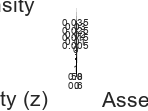

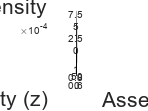

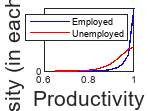

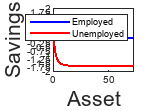

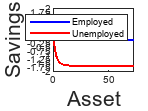

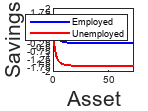

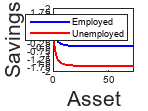

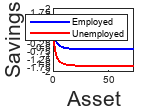

    filenamee = sprintf('Mats - Welfare/Omega_e - %s.mat', taupct);
    save(filenamee,'Omega_e');
    filenameu = sprintf('Mats - Welfare/Omega_u - %s.mat', taupct);
    save(filenameu,'Omega_u');

    filenamece = sprintf('Mats - Consumption/ce - %s.mat', taupct);
    save(filenamece,'ce');
    filenamecu = sprintf('Mats - Consumption/cu - %s.mat', taupct);
    save(filenamecu,'cu');

    filenamexie = sprintf('Mats - Savings/xie - %s.mat', taupct);
    save(filenamexie,'xie');
    filenamexiu = sprintf('Mats - Savings/xiu - %s.mat', taupct);
    save(filenamexiu,'xiu');
    
    filenameJV = sprintf('Mats - Job Value and Wage/JV - %s.mat', taupct);
    save(filenameJV,'JfIJ');
    filenamewg = sprintf('Mats - Job Value and Wage/wg - %s.mat', taupct);
    save(filenamewg,'wg');

    filenameGe = sprintf('Mats - Distributions/Ge - %s.mat', taupct);
    save(filenameGe,'Ge');
    filenameGu = sprintf('Mats - Distributions/Gu - %s.mat', taupct);
    save(filenameGu,'Gu');

    filenamepi = sprintf('Mats - Job Value and Wage/pi - %s.mat', taupct);
    save(filenamepi,'pi');

    filenameWe = sprintf('Mats - Value Function/We - %s.mat', taupct);
    save(filenameWe,'We');
    filenameWu = sprintf('Mats - Value Function/Wu - %s.mat', taupct);
    save(filenameWu,'Wu');
end


writetable(Results, 'Results/Results00.xlsx');
writetable(Omegas,  'Results/Welfare00.xlsx');

toc;

Elapsed time is 1426.765825 seconds.
